load('EncoderSim\encoder.mat');
T = 1;
omega_L = (2*pi/N)*e(:, 1)/T;  
omega_R = (2*pi/N)*e(:, 2)/T;
v_L = R*omega_L;
v_R = R*omega_R;

u_v = (v_L + v_R)/2;
omega_v = (v_L - v_R)/L;

t = 0:1:length(e)-1;

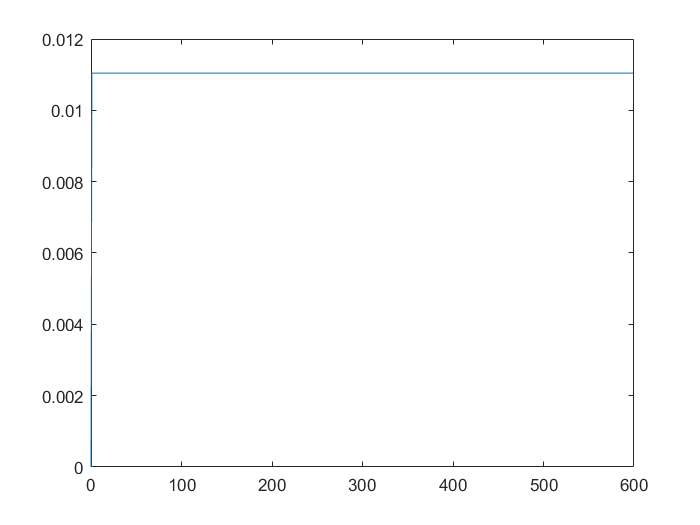

plot(t, omega_v);

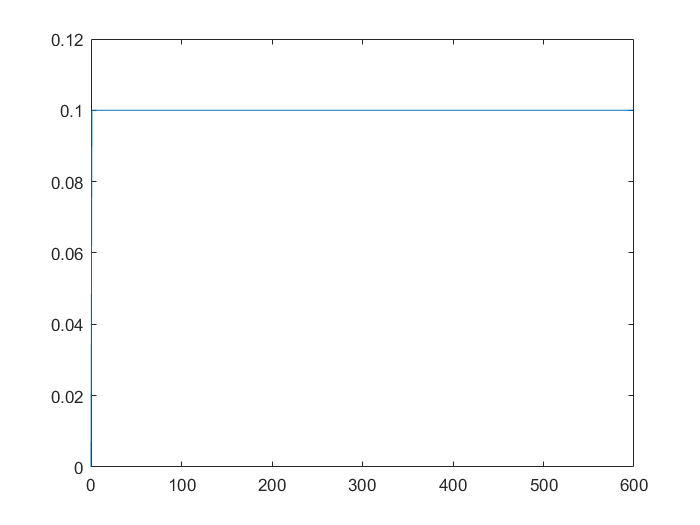

plot(t, u_v);

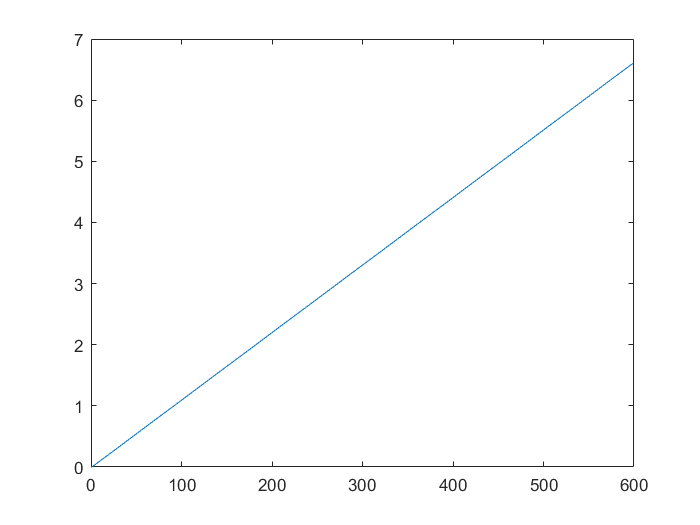


psi_k = yaw_angle(e, L, N, R);
plot(t, psi_k);

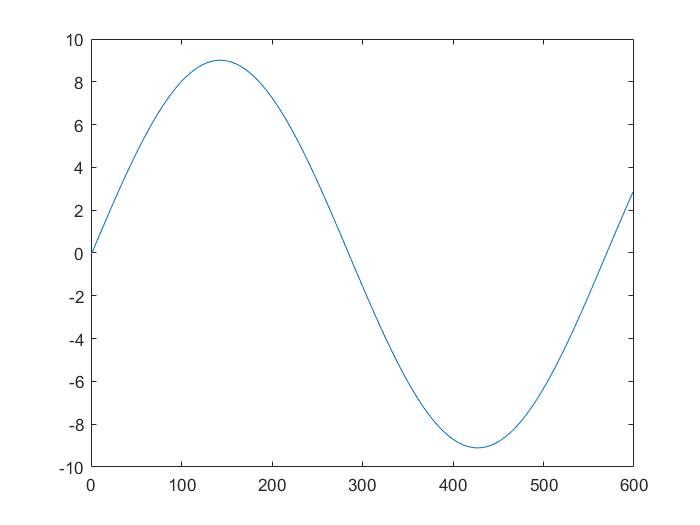

T_EV = position_vector(e, psi_k, N, R);
plot(t, T_EV(:,1));

plot(t, T_EV(:,1));